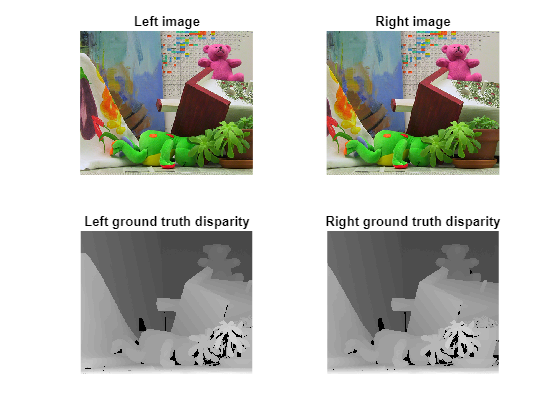

% In this part: 
% - cost volumes calculation
% - aggregation (with different filters)
% - disparity aqcuisition (winner-takes-all)
% - left-to-right correspondance check
% - occlusion filling
% - left-to-right correspondance check
% - confidence analysis
% - outlier filling 
% - cross-bilateral aggregation

clear;
close all;
clc;

dataset = 'teddy'; factor = 4;

L = imread([dataset,'\view1.png']);
R = imread([dataset,'\view5.png']);
GTL = round(single(imread([dataset,'\disp1.png']))./factor);
GTR = round(single(imread([dataset,'\disp5.png']))./factor);


mindisp = 0;
maxdisp = ceil(max(GTL(:)));

figure;
subplot(221); imshow(L); title('Left image');
subplot(222); imshow(R); title('Right image');

subplot(223); imshow(GTL, [mindisp maxdisp]); title('Left ground truth disparity');
subplot(224); imshow(GTR, [mindisp maxdisp]); title('Right ground truth disparity');

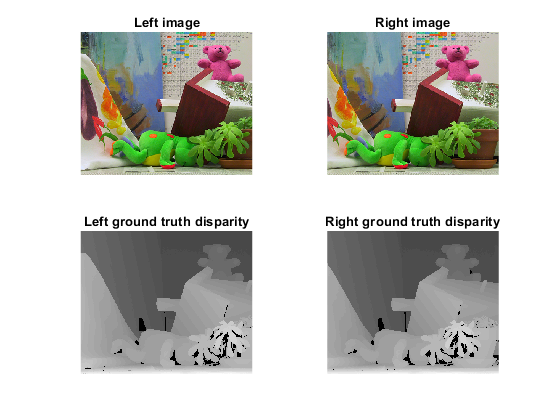

figure;
subplot(221); imshow(L); title('Left image');
subplot(222); imshow(R); title('Right image');

subplot(223); imshow(GTL, [mindisp maxdisp]); title('Left ground truth disparity');
subplot(224); imshow(GTR, [mindisp maxdisp]); title('Right ground truth disparity');

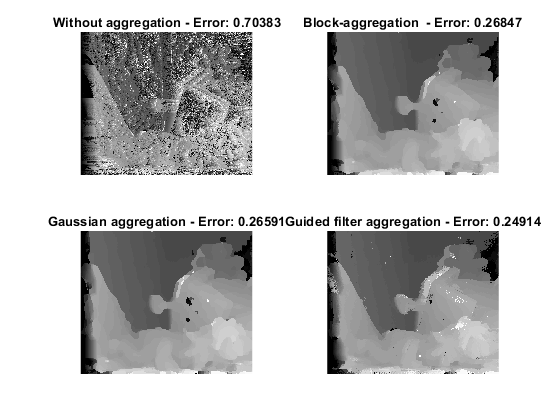

%% cost calculation
[CostL, CostR] = calculate_cost(L, R, maxdisp);
radius = 9;

figure;

% no aggregation + winner-takes-all
DispL = winner_takes_all(CostL);
subplot(221); imshow(DispL, [mindisp maxdisp]); title(['Without aggregation - Error: ', num2str(calculate_error(DispL, GTL))]); drawnow;

% block aggregation + winner-takes-all
cost = aggregate_cost_block(CostL, radius);
[DispLeftBlock] = winner_takes_all(cost);

subplot(222);  imshow(DispLeftBlock, [mindisp maxdisp]); title(['Block-aggregation  - Error: ' num2str(calculate_error(DispLeftBlock, GTL))]); drawnow;

% gaussian aggregation + winner-takes-all
sigma = 10;
cost = aggregate_cost_gauss(CostL, radius, sigma);
[DispLeftGauss] = winner_takes_all(cost);
DispLeftGauss = DispLeftGauss + mindisp;

subplot(223);  imshow(DispLeftGauss, [mindisp maxdisp]); title(['Gaussian aggregation - Error: ', num2str(calculate_error(DispLeftGauss, GTL))]); drawnow;
 
% guided filter aggregation + winner-takes-all
smoothValue = 100;
cost = aggregate_cost_guided(CostL, L, radius, smoothValue);
[DispLeftGuided] = winner_takes_all(cost);
DispLeftGuided = DispLeftGuided + mindisp;

subplot(224);  imshow(DispLeftGuided, [mindisp maxdisp]); title(['Guided filter aggregation - Error: ', num2str(calculate_error(DispLeftGuided, GTL))]); drawnow;

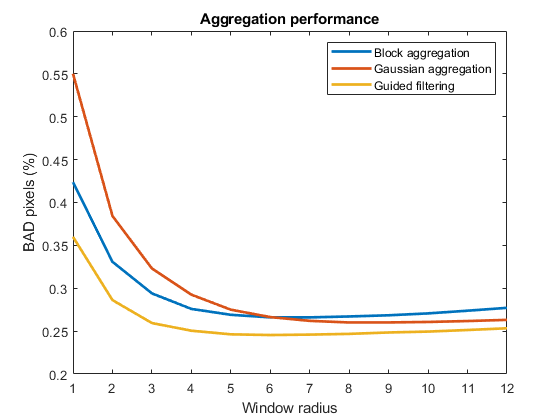

% Graphs about effect of radius
radii = 1:12;
names = {'Block aggregation', 'Gaussian aggregation', 'Guided filtering'};
h = figure;

ERRORS = ones(numel(radii), 3)*NaN;

for radius = radii
    % Block aggregation
    cost = aggregate_cost_block(CostL, radius);
    [disptmp] = winner_takes_all(cost);
    ERRORS(radius, 1) = calculate_error(disptmp, GTL);

    % Gaussian aggregation
    cost = aggregate_cost_gauss(CostL, radius, radius/2);
    [disptmp] = winner_takes_all(cost);
    ERRORS(radius, 2) = calculate_error(disptmp, GTL);
    
    % Guided filter aggregation
    cost = aggregate_cost_guided(CostL, L, radius, 1000);
    [disptmp] = winner_takes_all(cost);
    ERRORS(radius, 3) = calculate_error(disptmp, GTL);
       
    % Stop computation if the result window is closed
    if ~ishandle(h)
        break;
    end
      
    % Plot the results
    figure(h); 
    plot(radii, ERRORS, 'LineWidth', 2); 
    title('Aggregation performance'); 
    legend(names); 
    xlabel('Window radius');
    ylabel('BAD pixels (%)');
    xlim([radii(1), radii(end)])
    drawnow;
    
end

clear disptmp;

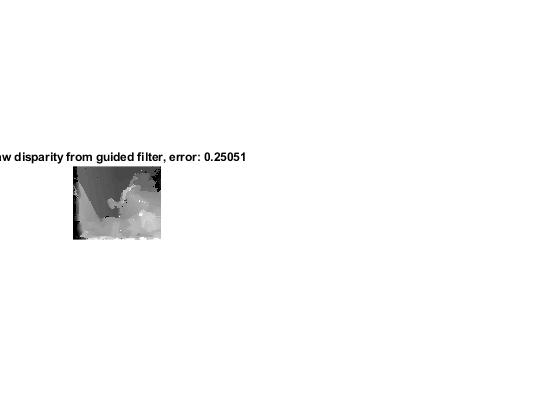

mindisp = 0;
maxdisp = ceil(max(GTL(:)));


% Computing costs and disparity maps in the same way as in 
% the mandatory steps for analysis
smoothingAmount = 100;
radius = 11;

[CostL, CostR] = calculate_cost(L, R, maxdisp);
guidedCostL = aggregate_cost_guided(CostL, L, radius, smoothingAmount);
guidedCostR = aggregate_cost_guided(CostR, R, radius, smoothingAmount);

[DispLeftGuided] = winner_takes_all(guidedCostL);
[DispRightGuided] = winner_takes_all(guidedCostR);

h = figure; subplot(1, 4, 1);
imshow(DispLeftGuided, [0 maxdisp]); title([ 'Raw disparity from guided filter, error: ', num2str(calculate_error(DispLeftGuided, GTL))]);  

## Left-to-Right correspondance check

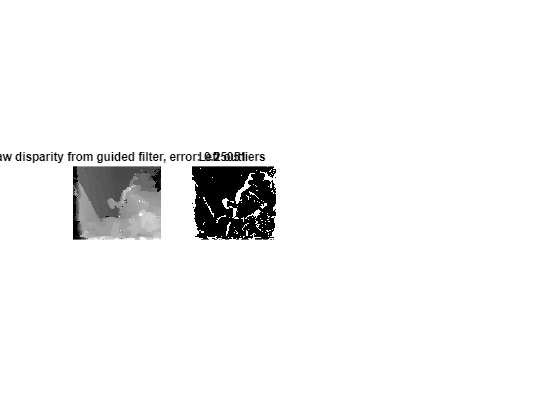

[outliersL, ~] = consistency_check(DispLeftGuided, DispRightGuided, 1);
subplot(1, 4, 2); imshow(outliersL, [0 1]); title('Left outliers'); 

## Confidence analysis

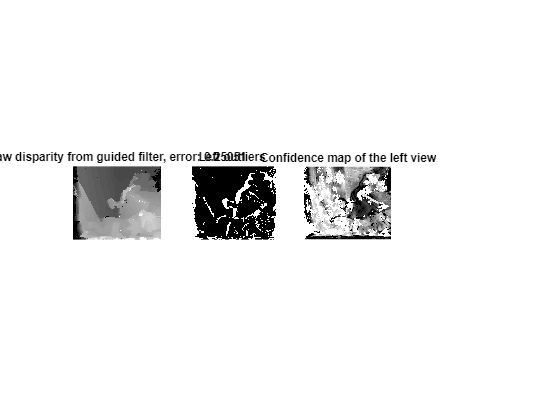

ConfL = comp_confidence(guidedCostL);
subplot(1, 4, 3); imshow(ConfL, [0 1]); title('Confidence map of the left view');  

## Outlier Filling

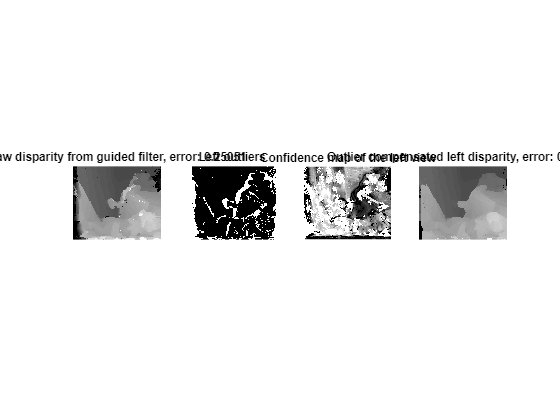

DispLeftGuided_filled = fill_blanks(DispLeftGuided, outliersL, ConfL);    
subplot(1, 4, 4); imshow(DispLeftGuided_filled, [mindisp maxdisp]); 
title([ 'Outlier compensated left disparity, error: ', num2str(calculate_error(DispLeftGuided_filled, GTL))]);  

## Cross-bilateral aggregation

sigma_spatial = 7;
sigma_intensity = 0.1;

% Perform cross-bilateral aggregation
bilateralCostL = aggregate_cost_crossbilateral(CostL, L, radius, sigma_spatial, sigma_intensity);
bilateralCostR = aggregate_cost_crossbilateral(CostR, R, radius, sigma_spatial, sigma_intensity);

% Compute disparity maps using winner-takes-all
DispLeftBilateral = winner_takes_all(bilateralCostL);
DispRightBilateral = winner_takes_all(bilateralCostR);

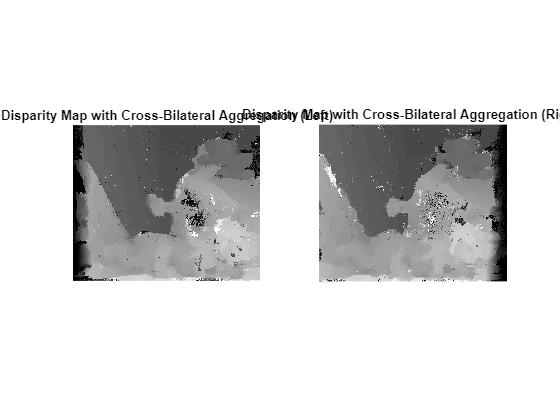

% Display the results
y = figure; subplot(1, 2, 1);
imshow(DispLeftBilateral, [mindisp maxdisp]);
title('Disparity Map with Cross-Bilateral Aggregation (Left)');
figure(y); subplot(1, 2, 2);
imshow(DispRightBilateral, [mindisp maxdisp]);
title('Disparity Map with Cross-Bilateral Aggregation (Right)');

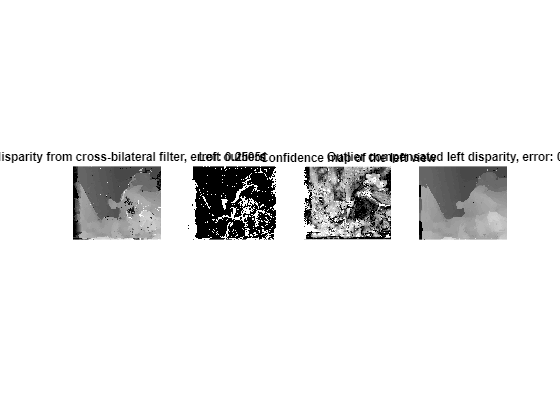

h = figure; subplot(1, 4, 1);
imshow(DispLeftBilateral, [0 maxdisp]); title([ 'Raw disparity from cross-bilateral filter, error: ', num2str(calculate_error(DispLeftGuided, GTL))]);  
[outliersL, ~] = consistency_check(DispLeftBilateral, DispRightBilateral, 1);
figure(h); subplot(1, 4, 2); imshow(outliersL, [0 1]); title('Left outliers'); 
ConfL = comp_confidence(bilateralCostL);
figure(h); subplot(1, 4, 3); imshow(ConfL, [0 1]); title('Confidence map of the left view');  
DispLeftGuided_filled = fill_blanks(DispLeftBilateral, outliersL, ConfL);    
figure(h); subplot(1, 4, 4); imshow(DispLeftGuided_filled, [mindisp maxdisp]); 
title([ 'Outlier compensated left disparity, error: ', num2str(calculate_error(DispLeftGuided_filled, GTL))]);  